% Get all the images and store in cell array 
dir = uigetdir;
picDir = cell(882, 2);
for i = 1 : 1 : 882
    fn = strcat(dir, '/', num2str(i), '/', num2str(i), '.tif');
    f = imread(fn);
    picDir{i,1} = f;
end

% Create the mask for each image. 0 is background, 1 is single, 2 is double,
for i = 1 : 1 : 882
    mask = zeros(32, 256);
    load(strcat(dir, '/', num2str(i), '/data.mat'));
    numBoutons = size(box, 1);
    
    for j = 1 : 1 : numBoutons
        temp = masks_top{j, 1};

        for x = 1 : 1 : size(temp, 1)
            for y = 1 : 1 : size(temp,2)
                if temp(x,y) && strcmp(box{j,2}, "single")
                    mask(x,y) = 1;
                elseif temp(x,y) && strcmp(box{j,2}, "both")
                    mask(x,y) = 2;
                end
            end
        end
    end
    picDir{i, 2} = mask;
end

% Split into 50% train 50% test
size_Train = 441;
size_Test = 441;
dataTrain = picDir(1:size_Train, :);
dataTest = picDir(size_Train:882, :);

% Create the datapoints x_i = [R; G; B] and calculate mean
mu_0 = [];
mu_1 = [];
mu_2 = [];
prior_0 = 0;
prior_1 = 0;
prior_2 = 0;
count = 0;
for train = 1 : 1 : 100
    image_temp = picDir{train, 1};
    mask_temp = picDir{train, 2};
    for x = 1 : 1 : 32
        for y = 1 : 1 : 256
            data = [image_temp(x,y,1); image_temp(x,y,2)];
            if mask_temp(x,y) == 0
                mu_0 = cat(2, mu_0, data);
            end
            if mask_temp(x,y) == 1
                mu_1 = cat(2, mu_1, data);
            end
            if mask_temp(x,y) == 2
                mu_2 = cat(2, mu_2, data);
            end
        end
    end
end
mu_0 = mean(mu_0, 2);
mu_1 = mean(mu_1, 2);
mu_2 = mean(mu_2, 2);

% Calculate Covariance Matrix
cov_0 = zeros(2,1)

cov_0 =      0
     0


cov_1 = zeros(2,1);
cov_2 = zeros(2,1);
count0 = 0;
count1 = 0;
count2 = 0;
for train = 1 : 1 : 100
    image_temp = picDir{train, 1};
    mask_temp = picDir{train, 2};
    for x = 1 : 1 : 32
        for y = 1 : 1 : 256
            data = [image_temp(x,y,1); image_temp(x,y,2)];
            data = double(data);
            if mask_temp(x,y) == 0
                cov_0 = cov_0 + (data - mu_0) * (data - mu_0)';
                count0 = count0 + 1;
            end
            if mask_temp(x,y) == 1
                cov_1 = cov_1 + (data - mu_1) * (data - mu_1)';
                count1 = count1 + 1;
            end
            if mask_temp(x,y) == 2
               cov_2 = cov_2 + (data - mu_2) * (data - mu_2)';
                count2 = count2 + 1;
            end
        end
    end
end
cov_0 = cov_0 / count0;
cov_1 = cov_1 / count1;
cov_2 = cov_2 / count2;

% Test probability 
 datapoint = double([tempImage(1,1, 1); tempImage(1,1, 2)]);

Unrecognized function or variable 'tempImage'.

 p_0 = exp(-0.5 * (datapoint - mu_0)' / cov_0 * (datapoint - mu_0)) / (2 * pi)^1.5 / (det(cov_0))^2
 p_1 = exp(-0.5 * (datapoint - mu_1)' / cov_1 * (datapoint - mu_1)) / (2 * pi)^1.5 / (det(cov_1))^2
 p_2 = exp(-0.5 * (datapoint - mu_2)' / cov_2 * (datapoint - mu_2)) / (2 * pi)^1.5 / (det(cov_2))^2

% Caculate Accuracy
totalPix = 0;
acc = 0;
maskTemp = zeros(32, 256);
for i = 1:1:50
    imageTest = dataTest{i, 1};
    maskTest = dataTest{i, 2};
    for x = 1:1:32
        for y = 1:1:256
            totalPix = totalPix + 1;
            datapoint = double([imageTest(x,y, 1); imageTest(x,y, 2)]);
            p_array = [exp(-0.5 * (datapoint - mu_0)' / cov_0 * (datapoint - mu_0)) / (2 * pi)^1.5 / (det(cov_0))^2, exp(-0.5 * (datapoint - mu_1)' / cov_1 * (datapoint - mu_1)) / (2 * pi)^1.5 / (det(cov_1))^2, exp(-0.5 * (datapoint - mu_2)' / cov_2 * (datapoint - mu_2)) / (2 * pi)^1.5 / (det(cov_2))^2];
            [maxP, maxI] = max(p_array);
            if (maxI - 1) == 0 && maskTest(x,y) == 0
                acc = acc + 1;
                maskTemp(x,y) = 0;
            elseif (maxI - 1) == 1 && maskTest(x,y) == 1
                acc = acc + 1;
                maskTemp(x,y) = 1;
            elseif (maxI - 1) == 2 && maskTest(x,y) == 2
                acc = acc + 1;
                maskTemp(x,y) = 1;
            end
        end
    end
end
accuracy = acc / totalPix;

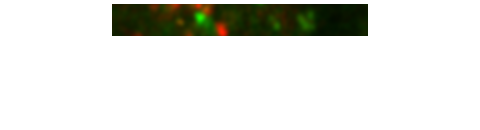

%Create mask
imshow(imageTest);

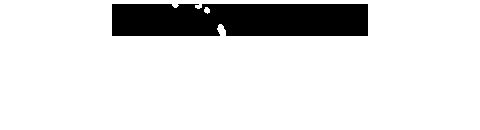

imshow(maskTemp);

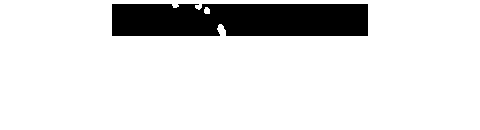

imshow(maskTest);